addpath('./datos')
addpath('./funciones')

Vamos a comparar la SNR obtenida con cuantificación escalar y vectorial en función de Rb.

**Tarea 2a**

Utilizando como datos la matriz training (tarea 3, sesión 1):

load training

Obtén con bsVQ cuantificadores vectoriales de 1 a 16 bits (thr = 0,01, ε = 0,025).

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).



for nbits = 1 : 16
    horaInicial = clock;
    [VQ, vDist] = bsVQ (training, nbits, 0.025, 0.01, 1);
    horaFinal=clock;
    vectorSegundosEstimacion(nbits,:) = etime(horaFinal, horaInicial);

Almacena los 16 VQs en una única matriz VQbst de forma que las dos primeras filas se correspondan con los centroides del VQ de 1 bit, las cuatro siguientes con los centroides del VQ de 2 bits, etc. 

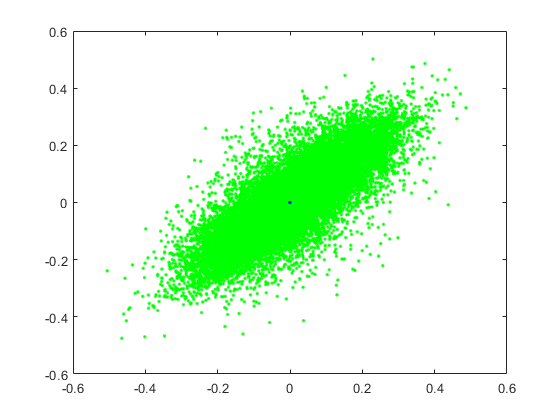

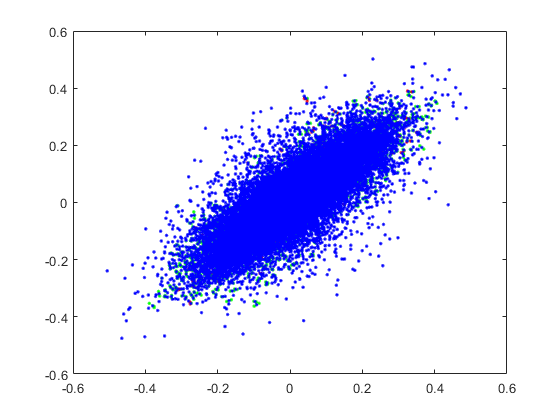

    if nbits == 1
        VQbst = VQ;
    else 
        VQbst = vertcat(VQbst, VQ);
    end
end

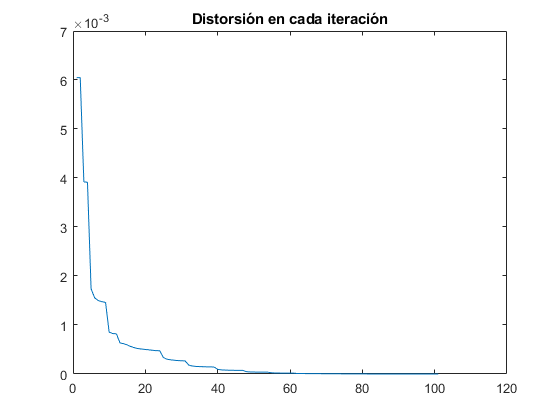

plot(vDist)
title("Distorsión en cada iteración")

Registra el tiempo que tarda en estimarse cada uno de los 16 VQs y represéntalo en función del número de bits. 

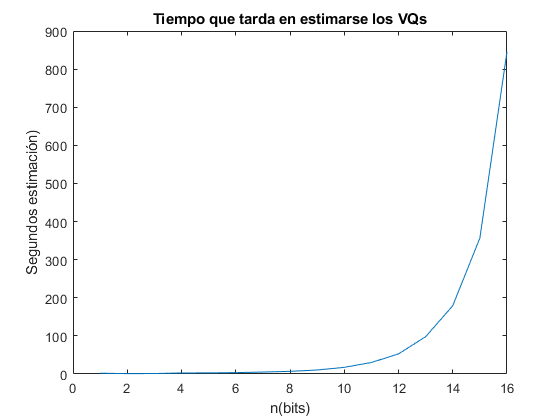

segundosEstimacion = sum(vectorSegundosEstimacion);
n=1:1:16;
figure
plot(n,vectorSegundosEstimacion)
grid
xlabel('n(bits)')
ylabel('Segundos estimación)')
title("Tiempo que tarda en estimarse los VQs")
grid

Guarda la matriz VQbst y los tiempos registrados en el fichero VQbst.mat.

save ('VQbst.mat', 'VQbst', 'vectorSegundosEstimacion');

save 2a.mat

**Tarea 2b**

Considerando la señal en tvg_training_5s.wav (¡trampa!): 

load ('VQbst.mat', 'VQbst', 'vectorSegundosEstimacion');

[valores_training_5s, fs_training_5s] = audioread('tvg_training_5s.wav');

data_5s=reshape(valores_training_5s',2,length(valores_training_5s)/2)';

SNRq_split=[];

for nbits = 1:1:16
    
    % Extraigo de la matriz VQt las filas correspondientes al VQ de nbits
    % de la iteración correspondiente
    if nbits == 1
        filainicial = 1;
        filafinal = 2;
    else 
        filainicial = filainicial + 2^(nbits-1);
        filafinal = filainicial + 2^nbits - 1;
    end
    
    VQi = VQbst (filainicial:filafinal, :);
     
    dataq_5s = VQuantize (data_5s, VQi);
   
    % Pares de muestras a vector adecuadamente ordenado

    temp=dataq_5s';
    
    y_5s=temp(:);

    % Tenéis un traspuesto en vuestra SNR por lo que tengo que añadir:

    y_5s=y_5s';

Representa la SNR global obtenida con los VQs en función del régimen binario.

    SNRq_split =  [SNRq_split, SNR(valores_training_5s, y_5s)];
   
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


xsc=1;
for n=1:1:8
    [training_5s_QMR_nb, e_training_5s_QMR_nb] = qmidriser(valores_training_5s, xsc, n);
    SNRq_QMR(n) = SNR(valores_training_5s, training_5s_QMR_nb);
end

Compárala con las gráficas obtenidas con un cuantificador escalar uniforme (qmidriser, xsc = 1) y con las aproximaciones SNR1 y SNR2.

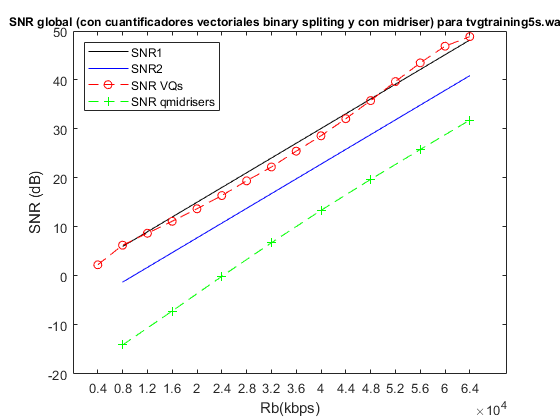

fs=8*10^3;
    
nb=1:1:16;
n=1:1:8;
Rb_1a16 = fs*(nb/2);  % Rb entre [4 kB - 64 kB]
Rb_1a8 = fs*n;
figure
plot(Rb_1a8,6.02*n,'k')
hold on;
plot(Rb_1a8,6.02*n-7.27,'b')
hold on;
%plot(Rb,SNRq(1:length(Rb)),'r--o');
plot(Rb_1a16,SNRq_split,'r--o');
ax = gca; 
ax.XTick = Rb_1a16; 
grid
hold on;plot(Rb_1a8,SNRq_QMR,'g--+');
ax = gca; 
ax.XTick = Rb_1a16; 
xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend({'SNR1','SNR2', 'SNR VQs','SNR qmidrisers'}, 'Location', 'northwest')
title("SNR global (con cuantificadores vectoriales binary spliting y con midriser) para tvgtraining5s.wav ", "FontSize",9)
grid

save 2b.mat

**Tarea 2c. Cuantificación escalar**

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

Diseñaremos un cuantificador escalar de 5 bits con la función bsVQ, utilizando como datos de entrenamiento tvg_training_20s.wav (thr = 0,01, ε = 0,025).

%data_5s=reshape(valores_training_5s',2,length(valores_training_5s)/2)'; %se podria hacer asi (creo)

%poner los valores en 2 columnas
[valores_training, fs_training] = audioread('tvg_training_20s.wav');
columna = 0; %para cambiar entre una columna y otra
fila = 1;
for i=1:length(valores_training)
    if columna == 0 %impar
        training(fila, 1) = valores_training (i);
        columna = 1;
    else %par
        training(fila, 2) = valores_training (i);
        columna = 0;
        fila = fila + 1;
    end
end

nbits = 5;
[VQ, vDist] = bsVQ (valores_training, nbits, 0.025, 0.01, 1);

De forma análoga a como se hizo para los cuantificadores uniformes, representa la característica de cuantificación del cuantificador estimado en el rango de valores de entrada de -1 a 1.

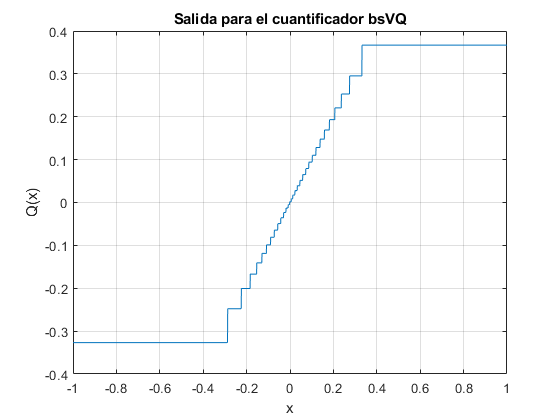

x = -1:0.001:1;
xsc = 1;

[y_20, dist_20] = VQuantize(x',VQ);

plot (x, y_20)
grid on
xlabel('x')
ylabel('Q(x)')
title('Salida para el cuantificador bsVQ')

Para la señal en tvg_training_5s.wav estima la SNR obtenida con el cuantificador diseñado. Sobre la gráfica obtenida en la subtarea anterior (con el mismo fichero) indica la situación del valor ahora obtenido.

[valores_training_5s, fs_training_5s]= audioread ('tvg_training_5s.wav');
[y_5, dist_5] = VQuantize(valores_training_5s, VQ);
snr5=SNR(valores_training_5s, y_5')

snr5 = 24.4767

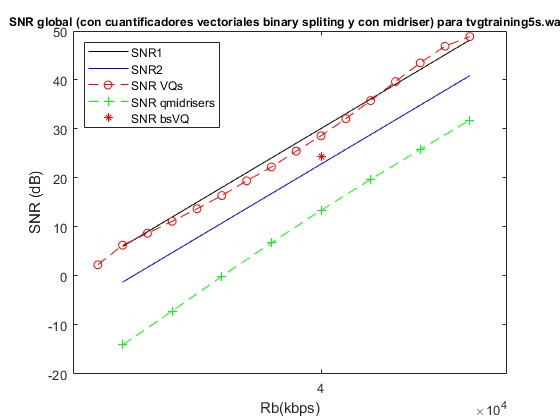

%codigo de la representacion de 2b para superponer el resultado de este
%apartado
    fs=8*10^3;
    
    nb=1:1:16;
    n=1:1:8;
    Rb_1a16 = fs*(nb/2);  % Rb entre [4 kB - 64 kB]
    Rb_1a8 = fs*n;
    figure
    plot(Rb_1a8,6.02*n,'k')
    hold on;
    plot(Rb_1a8,6.02*n-7.27,'b')
    hold on;
    %plot(Rb,SNRq(1:length(Rb)),'r--o');
    plot(Rb_1a16,SNRq_split,'r--o');
    ax = gca; 
    ax.XTick = Rb_1a16; 
    grid
    hold on;plot(Rb_1a8,SNRq_QMR,'g--+');
    ax = gca; 
    ax.XTick = Rb_1a16; 

Rb_5bits = fs*5; %regimen binario 5 bits

hold on;plot(40000, snr5,'r*');
ax = gca; 
ax.XTick = 40000; 

xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend({'SNR1','SNR2', 'SNR VQs','SNR qmidrisers','SNR bsVQ'}, 'Location', 'northwest')
title("SNR global (con cuantificadores vectoriales binary spliting y con midriser) para tvgtraining5s.wav ", "FontSize",9)
grid